# Problem 1

interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

## Preliminary Calculations and Constants

Re = 6378.1; % Earth radius, km
mu = 398600.4415; % Earth mu, km^3/s^2


## Part a) i)

Current Orbit Characteristics:

e1 = 0; a1 = 1.025*Re; gamma1 = 0;

Final Orbit Characteristics:

e2 = 0; a2 = 6.611*Re; gamma2 = 0;

Transfer Orbit Characteristics:

aT = (a1 + a2)/2, eT = 1- a1/aT

aT = 2.4352e+04

eT = 0.7315

TOF_Hohmann = sqrt(aT^3/mu) * (pi - eT*sin(pi)), TOF_Hohmann_hr = TOF_Hohmann/3600

TOF_Hohmann = 1.8909e+04

TOF_Hohmann_hr = 5.2525

1st Thrust Point Conditions (Pre-Maneuver):

r1_mag = a1, v1_mag_0 = sqrt(mu*(2/r1_mag-1/a1)), v1_0 = [0 v1_mag_0];

r1_mag = 6.5376e+03

v1_mag_0 = 7.8084

1st Thrust Point Conditions (Post-Maneuver):

v1_mag_N = sqrt(mu*(2/r1_mag - 1/a2)), v1_N = [0 v1_mag_N];

v1_mag_N = 10.6061

dv1 = v1_N - v1_0, dv1_mag = norm(dv1)

dv1 =          0    2.7977


dv1_mag = 2.7977

2nd Thrust Point Conditions (Pre-Maneuver):

r2_mag = a2

r2_mag = 4.2166e+04

v2_mag_0 = sqrt(mu*(2/r2_mag - 1/aT)), v2_0 = [0 v2_mag_0]

v2_mag_0 = 1.5931

v2_0 =          0    1.5931


2nd Thrust Point Conditions (Post-Maneuver):

v2_mag_N = sqrt(mu*(2/r2_mag - 1/a2)), v2_N = [0 v2_mag_N]

v2_mag_N = 3.0746

v2_N =          0    3.0746


dv2 = v2_N - v2_0, dv2_mag = norm(dv2)

dv2 =          0    1.4815


dv2_mag = 1.4815

dv_mag_total = dv1_mag + dv2_mag

dv_mag_total = 4.2792

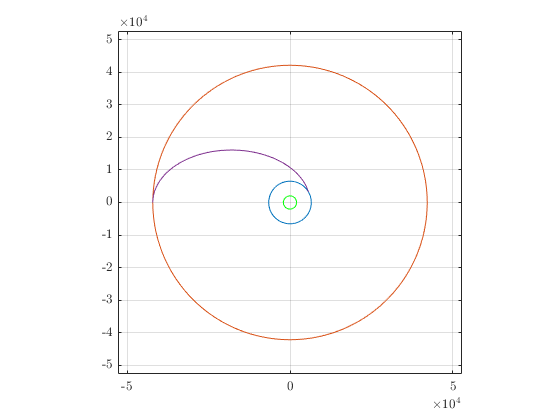

aT_2 = 2.4165e+04

eT_2 = 0.7449

ths1_2 = 0.5236

E1_2 = 0.2042

TOF_total_2 = 1.8376e+04

v1_0_2 =          0    7.8084


v1_N_2 =          0   10.6061


dv1_2 =          0    2.7977


v2_0_2 =          0    1.5528


v2_N_2 =          0    3.0746


dv2_2 =          0    1.5218


dv_mag_total_2 = 4.3195



[aT_2, eT_2, ths1_2, E1_2, TOF_total_2, ...
    v1_0_2, v1_N_2, dv1_2, ...
    v2_0_2, v2_N_2, dv2_2, dv_mag_total_2] = coplanartransfer(a1,a2,150*pi/180,mu,1)

### Function 1: Transfer Characteristics

Transfer starting at periapsis of transfer orbit to transfer angle on orbit

a1 and a2 in km, transfer_angle in radians

function [aT, eT, ths1, E1, TOF_total, v1_0, v1_N, dv1, v2_0, v2_N, dv2, dv_mag_total] = coplanartransfer(a1,a2,transfer_angle,mu,holdstatus)

Transfer Orbit Characteristics:

ths1 = pi-transfer_angle;
eT = (a2 - a1)/(a2 + a1 * cos(ths1));
aT = a2/(1+eT);
E1 = eccenAnom(ths1,eT);
TOF1 = sqrt(aT^3/mu) * (E1 - eT*sin(E1));
TOF2 = sqrt(aT^3/mu) * (pi - eT*sin(pi));
TOF_total = TOF2-TOF1;

1st Thrust Point Conditions (Pre-Maneuver):

r1_mag = a1; v1_mag_0 = sqrt(mu*(2/r1_mag-1/a1)); v1_0 = [0 v1_mag_0];

1st Thrust Point Conditions (Post-Maneuver):

v1_mag_N = sqrt(mu*(2/r1_mag - 1/a2)); v1_N = [0 v1_mag_N];
dv1 = v1_N - v1_0; dv1_mag = norm(dv1);

2nd Thrust Point Conditions (Pre-Maneuver):

r2_mag = a2;
v2_mag_0 = sqrt(mu*(2/r2_mag - 1/aT)); v2_0 = [0 v2_mag_0];

2nd Thrust Point Conditions (Post-Maneuver):

v2_mag_N = sqrt(mu*(2/r2_mag - 1/a2)); v2_N = [0 v2_mag_N];
dv2 = v2_N - v2_0; dv2_mag = norm(dv2);
dv_mag_total = dv1_mag + dv2_mag;

Plot Original and Final Orbits:

if holdstatus == 1
    ths_plot = linspace(0,2*pi,1000);
    rx_i = a1 * cos(ths_plot); ry_i = a1 * sin(ths_plot);
    rx_f = a2 * cos(ths_plot); ry_f = a2 * sin(ths_plot);
    plot(rx_i,ry_i), hold on, plot(rx_f,ry_f)
    grid on
    axis equal
    xlim([-a2 a2]*1.25), ylim([-a2 a2]*1.25)
    plot(0,0,'go','MarkerSize', 10)
end

Plot Transfer:

ths_plot_T = linspace(ths1,pi,1000);
r_T_plot = aT * (1-eT^2)./(1+eT*cos(ths_plot_T));
rx_T = r_T_plot.*cos(ths_plot_T); ry_T = r_T_plot.*sin(ths_plot_T);
plot(rx_T,ry_T)
if holdstatus == 1
    hold on
else
    hold off
end
end

### Function 4: Eccentric Anomaly 

function E = eccenAnom(ths,e)
    E = 2*atan(sqrt((1-e)/(1+e))*tan(ths/2));
end